fs_list = [100, 8000, 20000];  % low, Nyquist for low, Nyquist for Band
N_sinc = 20;

t_sample_all = {};
x_sample_orig_all = {};
x_sample_low_all = {};
x_sample_band_all = {};

for i = 1:length(fs_list)
    fs_samp = fs_list(i);
    
    [t_sample_orig, x_sample_orig] = sample_signal(t, x, fs_samp);
    [~, x_sample_low] = sample_signal(t, x_low_filtered, fs_samp);
    [~, x_sample_band] = sample_signal(t, x_band_filtered, fs_samp);
    
    t_sample_all{i} = t_sample_orig;
    x_sample_orig_all{i} = x_sample_orig;
    x_sample_low_all{i} = x_sample_low;
    x_sample_band_all{i} = x_sample_band;
end

xr_orig_all = {};
xr_low_all = {};
xr_band_all = {};

for i = 1:length(fs_list)
    fs_samp = fs_list(i);

    % Reconstruct using previously saved sampled signals
    xr_orig_all{i}     = reconstruct(t, x_sample_orig_all{i}, fs_samp, N_sinc);
    xr_low_all{i}      = reconstruct(t, x_sample_low_all{i},  fs_samp, N_sinc);
    xr_band_all{i}     = reconstruct(t, x_sample_band_all{i}, fs_samp, N_sinc);
end

% --- Audio saving and MSE computation for each reconstructed signal ---
for i = 1:length(fs_list)
    fs_samp = fs_list(i);

    % Reconstructed signals
    x_orig_rec  = xr_orig_all{i};
    x_low_rec   = xr_low_all{i};
    x_band_rec  = xr_band_all{i};

    % Interpolate true signals to fs_samp time base for fair MSE comparison
    t_interp = 0:1/fs_samp:max(t);
    x_true      = interp1(t, x,              t_interp, 'linear');
    x_true_low  = interp1(t, x_low_filtered, t_interp, 'linear');
    x_true_band = interp1(t, x_band_filtered,t_interp, 'linear');

    % Reconstruct on the same time grid
    x_rec_interp      = interp1(t, x_orig_rec,     t_interp, 'linear');
    x_rec_low_interp  = interp1(t, x_low_rec,      t_interp, 'linear');
    x_rec_band_interp = interp1(t, x_band_rec,     t_interp, 'linear');

    % MSE Calculation
    mse_orig  = mean((x_true - x_rec_interp).^2);
    mse_low   = mean((x_true_low - x_rec_low_interp).^2);
    mse_band  = mean((x_true_band - x_rec_band_interp).^2);

    % Print to console
    fprintf('Sampling Rate = %d Hz\n', fs_samp);
    fprintf('  MSE (Original):    %.4e\n', mse_orig);
    fprintf('  MSE (Low-Pass):    %.4e\n', mse_low);
    fprintf('  MSE (Band-Pass):   %.4e\n\n', mse_band);

    % Normalize for safe audio export
    x_audio_orig = x_orig_rec  / max(abs(x_orig_rec));
    x_audio_low  = x_low_rec   / max(abs(x_low_rec));
    x_audio_band = x_band_rec  / max(abs(x_band_rec));

    % Save audio files
    audiowrite(sprintf('reconstructed_original_%dkHz.wav', fs_samp/1000), x_audio_orig, fs_samp);
    audiowrite(sprintf('reconstructed_lowpass_%dkHz.wav', fs_samp/1000),  x_audio_low,  fs_samp);
    audiowrite(sprintf('reconstructed_bandpass_%dkHz.wav', fs_samp/1000), x_audio_band, fs_samp);
end

Sampling Rate = 100 Hz


  MSE (Original):    8.2215e-30


  MSE (Low-Pass):    1.1856e-28


  MSE (Band-Pass):   4.5958e-30



Sampling Rate = 8000 Hz


  MSE (Original):    6.0869e-26


  MSE (Low-Pass):    5.5017e-25


  MSE (Band-Pass):   3.7010e-26



Sampling Rate = 20000 Hz


  MSE (Original):    2.9558e-05


  MSE (Low-Pass):    1.1062e-06


  MSE (Band-Pass):   1.9331e-05



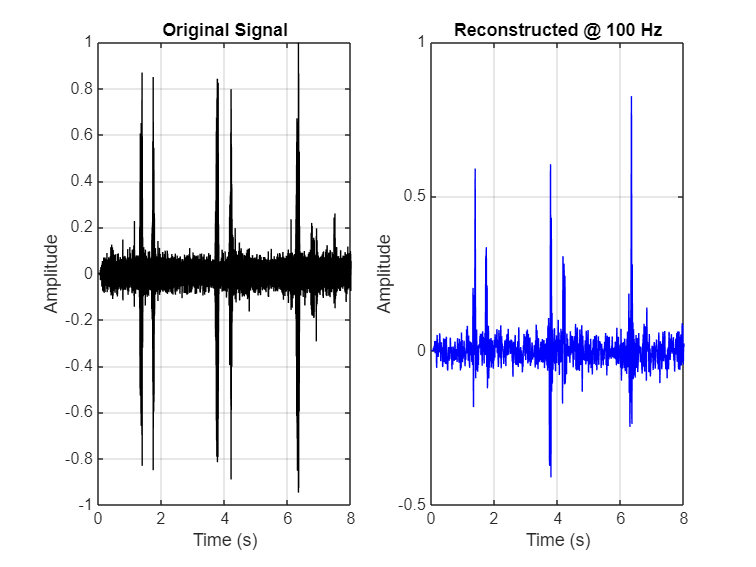

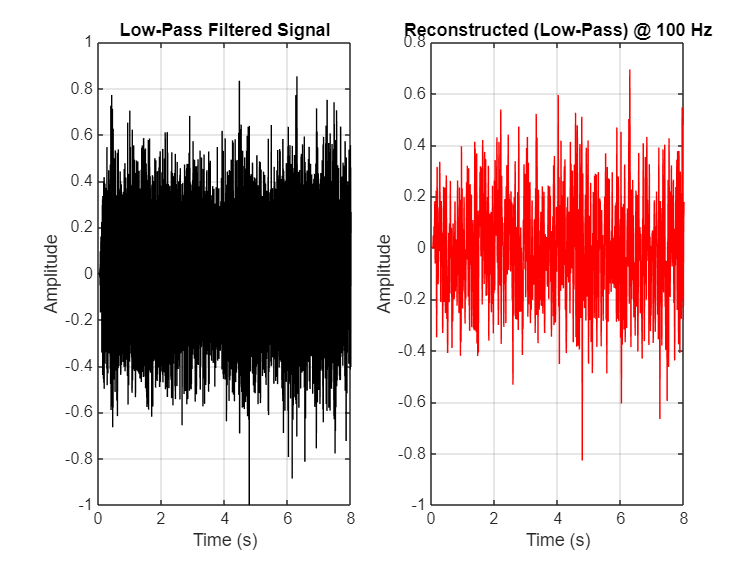

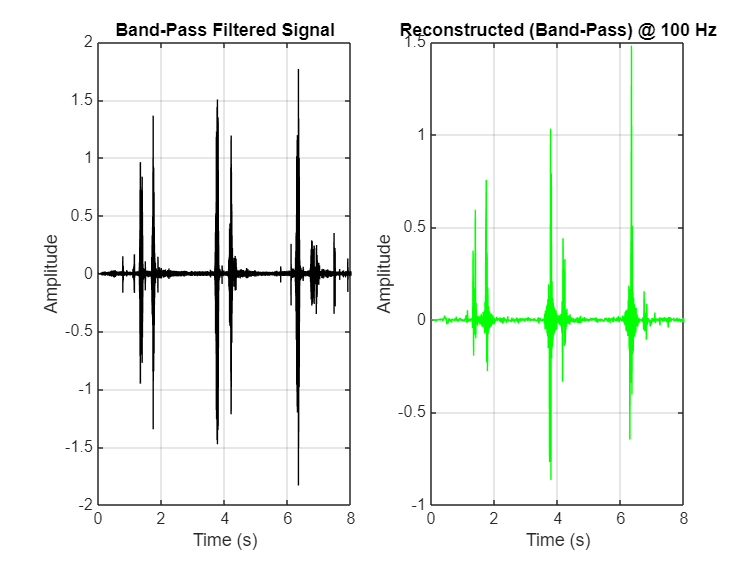

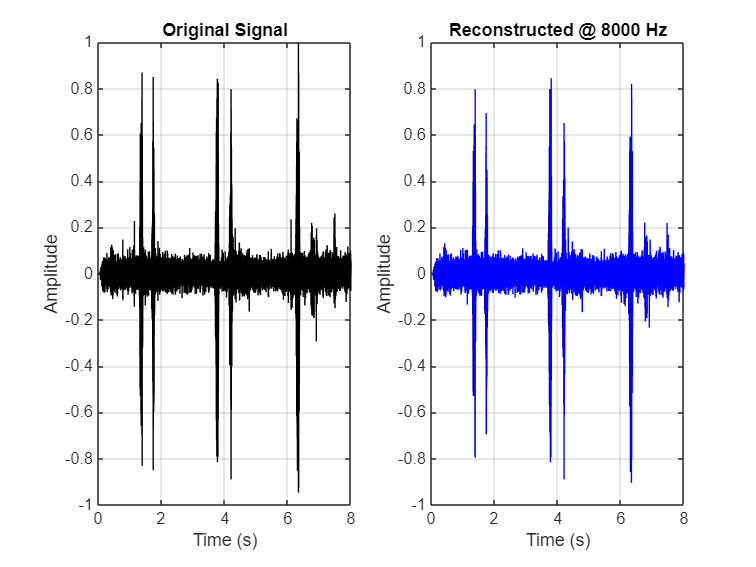

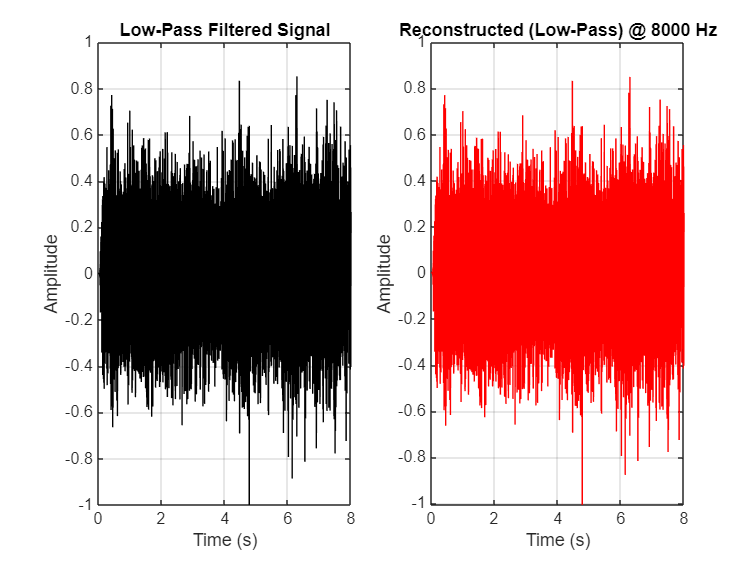

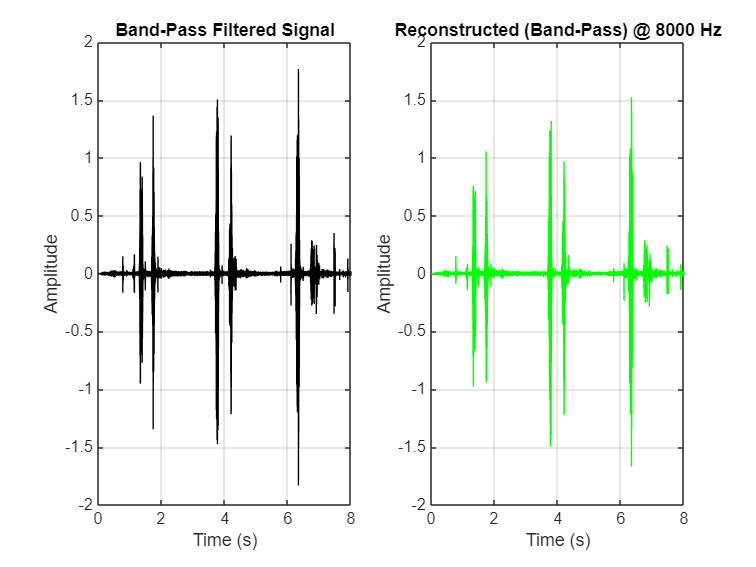

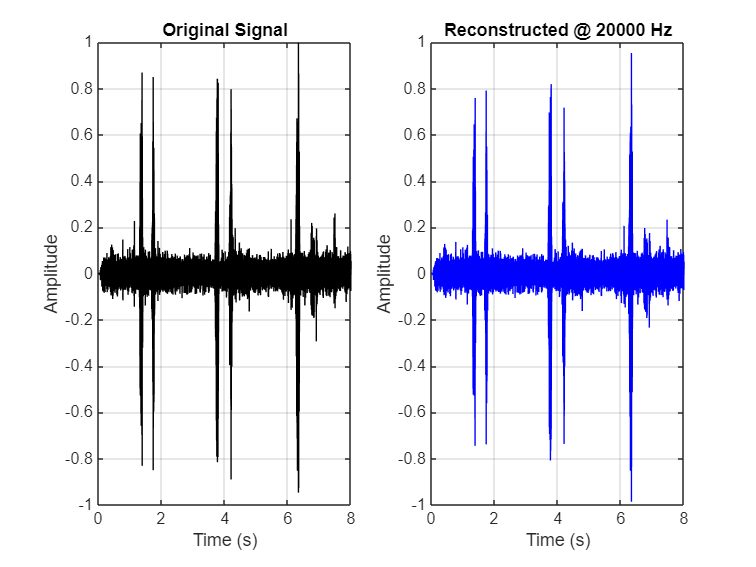

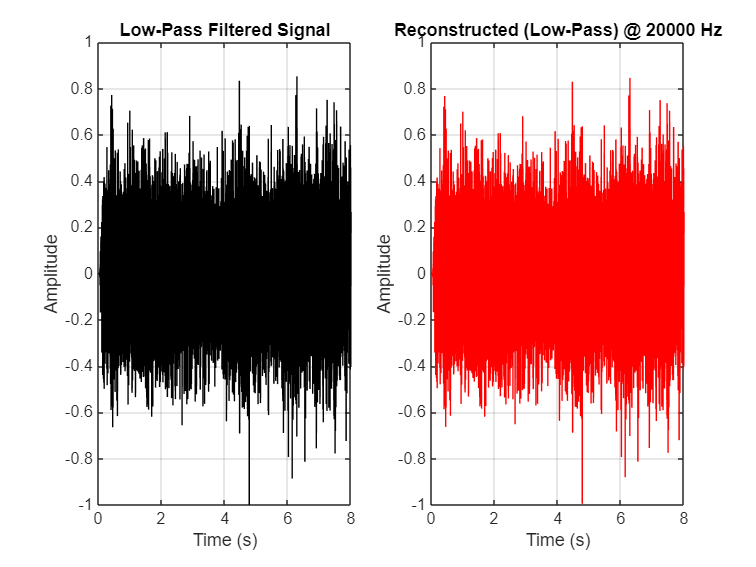

%% Stage 3 – Plotting: Time-Domain Reconstruction Comparisons (Figure 7.x)
for i = 1:length(fs_list)
    fs_samp = fs_list(i);

    % --- Original Signal ---
    figure;
    subplot(1,2,1);
    plot(t, x, 'k'); 
    title('Original Signal');
    xlabel('Time (s)'); ylabel('Amplitude'); 
    xlim([0 8]); % limit x-axis to 8 seconds
    grid on;

    subplot(1,2,2);
    plot(t, xr_orig_all{i}, 'b'); 
    title(['Reconstructed @ ', num2str(fs_samp), ' Hz']);
    xlabel('Time (s)'); ylabel('Amplitude'); 
    xlim([0 8]); % limit x-axis to 8 seconds
    grid on;

    % --- Low-Pass Filtered ---
    figure;
    subplot(1,2,1);
    plot(t, x_low_filtered, 'k'); 
    title('Low-Pass Filtered Signal');
    xlabel('Time (s)'); ylabel('Amplitude'); 
    xlim([0 8]); % limit x-axis to 8 seconds
    grid on;

    subplot(1,2,2);
    plot(t, xr_low_all{i}, 'r'); 
    title(['Reconstructed (Low-Pass) @ ', num2str(fs_samp), ' Hz']);
    xlabel('Time (s)'); ylabel('Amplitude'); 
    xlim([0 8]); % limit x-axis to 8 seconds
    grid on;

    % --- Band-Pass Filtered ---
    figure;
    subplot(1,2,1);
    plot(t, x_band_filtered, 'k'); 
    title('Band-Pass Filtered Signal');
    xlabel('Time (s)'); ylabel('Amplitude'); 
    xlim([0 8]); % limit x-axis to 8 seconds
    grid on;

    subplot(1,2,2);
    plot(t, xr_band_all{i}, 'g'); 
    title(['Reconstructed (Band-Pass) @ ', num2str(fs_samp), ' Hz']);
    xlabel('Time (s)'); ylabel('Amplitude'); 
    xlim([0 8]); % limit x-axis to 8 seconds
    grid on;
end

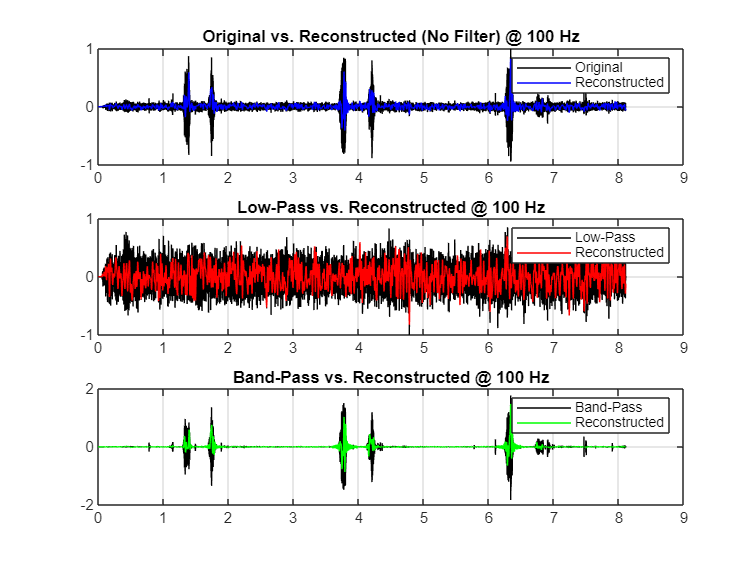

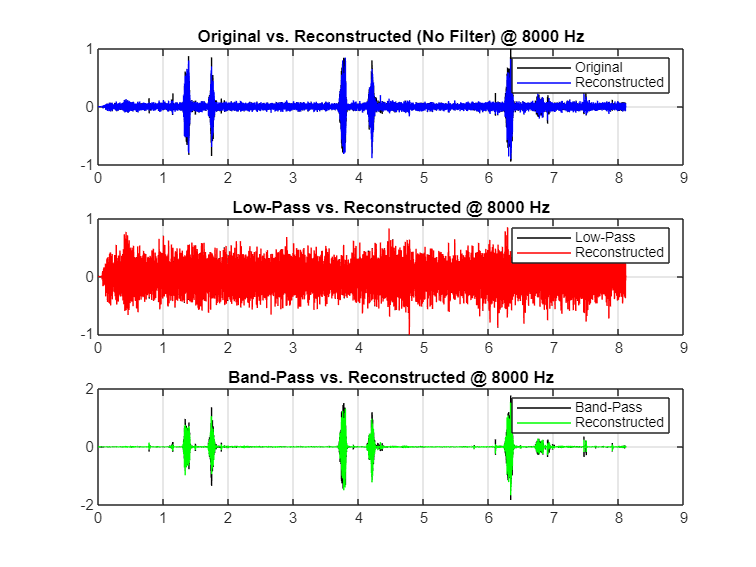

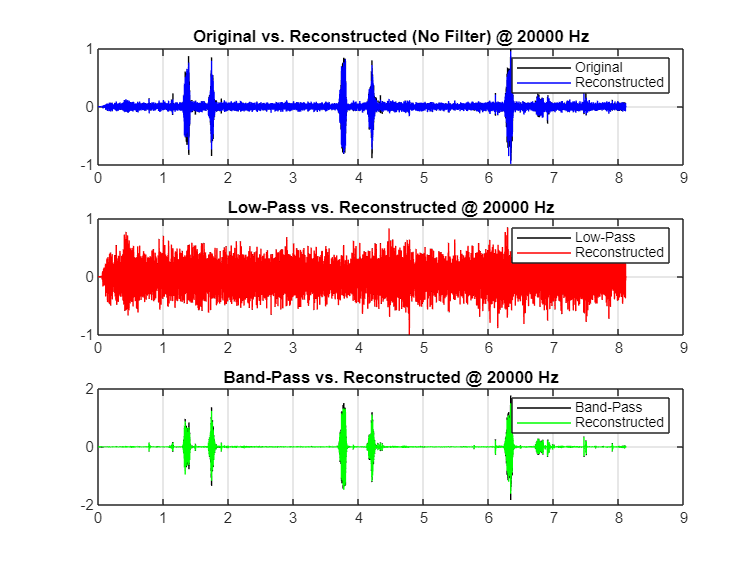

%% Aliasing Comparison (Sampled Points Only)
for i = 1:length(fs_list)
    fs_samp = fs_list(i);
    
    figure;
    subplot(3,1,1);
    plot(t, x, 'k'); hold on;
    plot(t, xr_orig_all{i}, 'b');
    title(['Original vs. Reconstructed (No Filter) @ ', num2str(fs_samp), ' Hz']);
    legend('Original', 'Reconstructed');
    grid on;

    subplot(3,1,2);
    plot(t, x_low_filtered, 'k'); hold on;
    plot(t, xr_low_all{i}, 'r');
    title(['Low-Pass vs. Reconstructed @ ', num2str(fs_samp), ' Hz']);
    legend('Low-Pass', 'Reconstructed');
    grid on;

    subplot(3,1,3);
    plot(t, x_band_filtered, 'k'); hold on;
    plot(t, xr_band_all{i}, 'g');
    title(['Band-Pass vs. Reconstructed @ ', num2str(fs_samp), ' Hz']);
    legend('Band-Pass', 'Reconstructed');
    grid on;
end